clearvars
flma_recCTD = 'GI03FLMA-RIM01-02-CTDMOG040-recovered_host-ctdmo_ghqr_sio_mule_instrument'; % FLMA Recovered 
flma_telCTD = 'GI03FLMA-RIM01-02-CTDMOG040-telemetered-ctdmo_ghqr_sio_mule_instrument'; % FLMA Telemetered 
flma_instCTD = 'GI03FLMA-RIM01-02-CTDMOG040-recovered_inst-ctdmo_ghqr_instrument_recovered'; % FLMA instrument 

flma_CTDrec7 = pull_CTD_Data_from_THREDDS('deployment0007',flma_recCTD);
flma_CTDinst7 = pull_CTD_Data_from_THREDDS('deployment0007',flma_instCTD); 

flma_recDO = 'GI03FLMA-RIS01-03-DOSTAD000-recovered_host-dosta_abcdjm_sio_instrument_recovered'; % FLMA Recovered 
flma_telDO = 'GI03FLMA-RIS01-03-DOSTAD000-telemetered-dosta_abcdjm_sio_instrument'; % FLMA Telemetered 

flma_DOrec7 = pull_DO_Data_from_THREDDS('deployment0007',flma_recDO);

file number = 1


ans = 'GI03FLMA-RIM01-02-CTDMOG040'

file number = 2


ans = 'GI03FLMA-RIM01-02-CTDMOG040'

file number = 3


ans = 'GI03FLMA-RIM01-02-CTDMOG040'

file number = 4


ans = 'GI03FLMA-RIM01-02-CTDMOG040'

file number = 5


ans = 'GI03FLMA-RIM01-02-CTDMOG040'

file number = 6


ans = 'GI03FLMA-RIM01-02-CTDMOG040'

blue = [0     0.44706     0.74118];
red = [0.85098     0.32549    0.098039];
yellow = [0.92941     0.69412     0.12549];
purple = [0.49412     0.18431     0.55686];
green = [0.46667     0.67451     0.18824];
cyan = [0.30196      0.7451     0.93333];
maroon = [0.63529    0.078431     0.18431];
grey = [0.5 0.5 0.5];
lightcyan = [0.67843 0.92157 1];
brightpurple = [0.74902           0     0.74902];
forestgreen = [0     0.49804           0];
teal = [0     0.74902     0.74902];
navy = [0.078431     0.16863     0.54902];

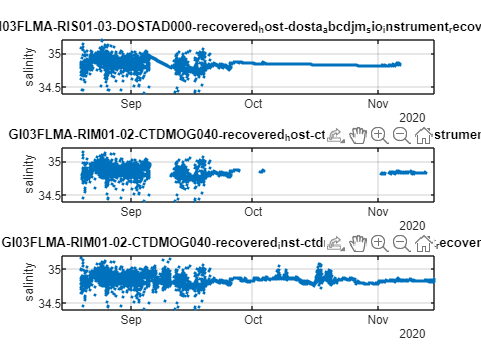

dt1 = datetime(2020,08,15); dt1.TimeZone = 'UTC';
dt2 = datetime(2020,11,15); dt2.TimeZone = 'UTC';

figure
subplot(3,1,1)
plot(flma_DOrec7.DOdt,flma_DOrec7.sea_water_practical_salinity,'.')
ylim([34.4 35.2])
xlim([dt1 dt2])
ylabel('salinity')
title(flma_recDO)
grid on

subplot(3,1,2)
plot(flma_CTDrec7.dt,flma_CTDrec7.practical_salinity,'.')
ylim([34.4 35.2])
xlim([dt1 dt2])
title(flma_recCTD)
ylabel('salinity')
grid on

subplot(3,1,3)
plot(flma_CTDinst7.dt,flma_CTDinst7.practical_salinity,'.')
ylim([34.4 35.2])
xlim([dt1 dt2])
ylabel('salinity')
title(flma_instCTD)
grid on

cd('G:\Shared drives\NSF_Irminger\OOI_DO_fixed_depth\Data')
load flma_CTD.mat
load flma_DO.mat

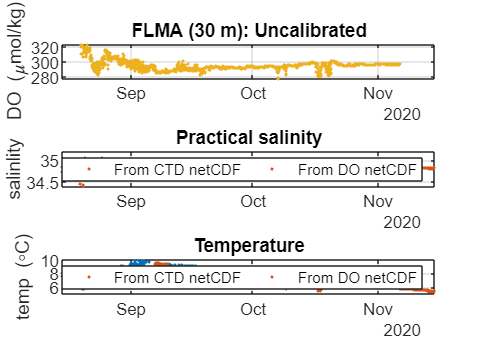

dt1 = datetime(2020,08,15); dt1.TimeZone = 'UTC';
dt2 = datetime(2020,11,15); dt2.TimeZone = 'UTC';
set(0,'defaultaxesfontsize',14);
set(0,'defaulttextfontsize',14);
figure
ax1 = subplot(3,1,1);
plot(flmaDO5.DOdt,flmaDO5.dissolved_oxygen,'.')
hold on
plot(flmaDO6.DOdt,flmaDO6.dissolved_oxygen,'.')
plot(flmaDO7.DOdt,flmaDO7.dissolved_oxygen,'.')
plot(flmaDO8.DOdt,flmaDO8.dissolved_oxygen,'.')
title('FLMA (30 m): Uncalibrated')
xlim([dt1 dt2])
grid on
ylabel('DO (\mumol/kg)')

ax2 = subplot(3,1,2);
plot(flmaCTD5.dt,flmaCTD5.practical_salinity,'.','Color',red)
hold on
plot(flmaCTD6.dt,flmaCTD6.practical_salinity,'.','Color',red)
plot(flmaCTD7.dt,flmaCTD7.practical_salinity,'.','Color',red)
plot(flmaCTD8.dt,flmaCTD8.practical_salinity,'.','Color',red)

plot(flmaDO5.DOdt,flmaDO5.sea_water_practical_salinity,'.','Color',blue)
plot(flmaDO6.DOdt,flmaDO6.sea_water_practical_salinity,'.','Color',blue)
plot(flmaDO7.DOdt,flmaDO7.sea_water_practical_salinity,'.','Color',blue)
plot(flmaDO8.DOdt,flmaDO8.sea_water_practical_salinity,'.','Color',blue)
ylabel('salinlity')
ylim([34.4 35.2])
xlim([dt1 dt2])
grid on
legend('From CTD netCDF','From DO netCDF','Orientation','horizontal','Location','NE')
title('Practical salinity')

ax2 = subplot(3,1,3);
plot(flmaCTD5.dt,flmaCTD5.temperature,'.','Color',red)
hold on
plot(flmaCTD6.dt,flmaCTD6.temperature,'.','Color',red)
plot(flmaCTD7.dt,flmaCTD7.temperature,'.','Color',red)
plot(flmaCTD8.dt,flmaCTD8.temperature,'.','Color',red)

plot(flmaDO5.DOdt,flmaDO5.sea_water_temperature,'.','Color',blue)
plot(flmaDO6.DOdt,flmaDO6.sea_water_temperature,'.','Color',blue)
plot(flmaDO7.DOdt,flmaDO7.sea_water_temperature,'.','Color',blue)
plot(flmaDO8.DOdt,flmaDO8.sea_water_temperature,'.','Color',blue)
ylabel('temp (\circC)')
title('Temperature')
xlim([dt1 dt2])
grid on
legend('From CTD netCDF','From DO netCDF','Orientation','horizontal','Location','NE')

function deployment = pull_CTD_Data_from_THREDDS(deploy_num,asset)
%   deploy_num = 'deployment0012' % string of deployment you want 
options = weboptions('Timeout', 600);

% asset = 'GI03FLMA-RIS01-03-DOSTAD000-recovered_host-dosta_abcdjm_sio_instrument_recovered'; % APEX NSIF
base_catalog_url = 'https://thredds.dataexplorer.oceanobservatories.org/thredds/catalog/ooigoldcopy/public/';

catalog = webread(strcat(base_catalog_url,asset,'/catalog.html'),options);
nclist = regexp(catalog,'<a href=''([^>]+.nc)''>','tokens');
base_url = 'https://thredds.dataexplorer.oceanobservatories.org/thredds/dodsC/';

% Find CTD files
[~, CTDind] = find(contains(string(nclist),deploy_num) == 1); % & ~contains(string(nclist),'CTD') & ~contains(string(nclist),'flort')...
    %& ~contains(string(nclist),'METBK'));

bigfile = [];
     for i = 1:length(CTDind)
           
        CTD_url_thredds = nclist{1,CTDind(i)}{1,1}; 
        CTD_url_thredds = strcat(base_url,CTD_url_thredds(22:end),'#fillmismatch');
%         ncdisp(CTD_url_thredds) % Displays all info for variables in netCDF
        vinfo = ncinfo(CTD_url_thredds);
          
                % time
                time = ncread(CTD_url_thredds,'time');
                dn = datenum(1900,1,1,0,0,0)+(time/60/60/24);
                file{i}.dt = datetime(dn,'ConvertFrom','datenum','TimeZone','UTC');
                file{i}.dn = dn;

                                % deployment/lat/lon
                file{i}.deployment = ncread(CTD_url_thredds,'deployment');
                lat = ncreadatt(CTD_url_thredds,'/','lat');
                lon = ncreadatt(CTD_url_thredds,'/','lon');
                file{i}.lat = ones(length(time),1)*lat;  
                file{i}.lon = ones(length(time),1)*lon; clear time CTDdn lat lon
                
                % pressure (dbar)
                file{i}.pressure = ncread(CTD_url_thredds,'sea_water_pressure');
                file{i}.pressure_qartod_results = ncread(CTD_url_thredds,'sea_water_pressure_qartod_results');
                pressure_qartod_executed = double(ncread(CTD_url_thredds,'sea_water_pressure_qartod_executed'));
                file{i}.pressure_qartod_executed = str2num(dec2bin(pressure_qartod_executed(1,:)));
                
                % temp 
                file{i}.temperature = ncread(CTD_url_thredds,'sea_water_temperature');
                file{i}.temperature_qartod_results = ncread(CTD_url_thredds,'sea_water_temperature_qartod_results');
                temperature_qartod_executed = double(ncread(CTD_url_thredds,'sea_water_temperature_qartod_executed'));
                file{i}.temperature_qartod_executed = str2num(dec2bin(temperature_qartod_executed(1,:)));
                
                % salinity 
                file{i}.practical_salinity = ncread(CTD_url_thredds,'sea_water_practical_salinity');
                file{i}.practical_salinity_qartod_results = ncread(CTD_url_thredds,'sea_water_practical_salinity_qartod_results');
                practical_salinity_qartod_executed = double(ncread(CTD_url_thredds,'sea_water_practical_salinity_qartod_executed'));
                file{i}.practical_salinity_qartod_executed = str2num(dec2bin(practical_salinity_qartod_executed(1,:)));
                
                % depth
                file{i}.depth = ncread(CTD_url_thredds,'depth');                             
                
                % Concatenate files into one big table 
                bigfile = [bigfile; struct2table(file{i})];
                bigfile.Properties.Description = asset; 
                
     end

deployment = bigfile; 

end




function deployment = pull_DO_Data_from_THREDDS(deploy_num,asset)
%   deploy_num = 'deployment0012' % string of deployment you want 
options = weboptions('Timeout', 600);

% asset = 'GI03FLMA-RIS01-03-DOSTAD000-recovered_host-dosta_abcdjm_sio_instrument_recovered'; % APEX NSIF
base_catalog_url = 'https://thredds.dataexplorer.oceanobservatories.org/thredds/catalog/ooigoldcopy/public/';

catalog = webread(strcat(base_catalog_url,asset,'/catalog.html'),options);
nclist = regexp(catalog,'<a href=''([^>]+.nc)''>','tokens');
base_url = 'https://thredds.dataexplorer.oceanobservatories.org/thredds/dodsC/';

% Find DOSTA files (excludes FLORT and CTD files 
[~, DOSTAind] = find(contains(string(nclist),deploy_num) == 1 & ~contains(string(nclist),'CTD') & ~contains(string(nclist),'flort')...
    & ~contains(string(nclist),'METBK'));

bigfile = [];
    for i = 1:length(DOSTAind)
           
        DOSTA_url_thredds = nclist{1,DOSTAind(i)}{1,1}; 
        DOSTA_url_thredds = strcat(base_url,DOSTA_url_thredds(22:end),'#fillmismatch');
%         ncdisp(DOSTA_url_thredds) % Displays all info for variables in netCDF
        vinfo = ncinfo(DOSTA_url_thredds);
        disp(['file number = ' num2str(i)])
%         disp({vinfo.Variables.Name}')
        ncreadatt(DOSTA_url_thredds,'sea_water_practical_salinity','instrument')

        VarCheck = max(strncmpi({vinfo.Variables.Name},'dissolved_oxygen',1));
    
            if VarCheck == 1
            
                % time
                time = ncread(DOSTA_url_thredds,'time');
                DOdn = datenum(1900,1,1,0,0,0)+(time/60/60/24);
                file{i}.DOdt = datetime(DOdn,'ConvertFrom','datenum','TimeZone','UTC');
                file{i}.DOdn = DOdn;
                
                % deployment/lat/lon
                file{i}.deployment = ncread(DOSTA_url_thredds,'deployment');
                lat = ncreadatt(DOSTA_url_thredds,'/','lat');
                lon = ncreadatt(DOSTA_url_thredds,'/','lon');
                file{i}.lat = ones(length(time),1)*lat;  
                file{i}.lon = ones(length(time),1)*lon; clear time DOdn lat lon
                
                % Oxygen
                file{i}.dissolved_oxygen = ncread(DOSTA_url_thredds,'dissolved_oxygen');
                file{i}.dissolved_oxygen_qc_executed = ncread(DOSTA_url_thredds,'dissolved_oxygen_qc_executed');
                file{i}.dissolved_oxygen_qc_results = ncread(DOSTA_url_thredds,'dissolved_oxygen_qc_results');

                % Ancillary 
                file{i}.optode_temperature = ncread(DOSTA_url_thredds,'optode_temperature');
                file{i}.sea_water_temperature = ncread(DOSTA_url_thredds,'sea_water_temperature');
                file{i}.sea_water_practical_salinity = ncread(DOSTA_url_thredds,'sea_water_practical_salinity');
%                 file{i}.pressure = ncread(DOSTA_url_thredds,'pressure');
                file{i}.estimated_oxygen_saturation = ncread(DOSTA_url_thredds,'estimated_oxygen_saturation');
                file{i}.estimated_oxygen_saturation_qc_executed = ncread(DOSTA_url_thredds,'estimated_oxygen_saturation_qc_executed');
                file{i}.estimated_oxygen_saturation_qc_results = ncread(DOSTA_url_thredds,'estimated_oxygen_saturation_qc_results');
             
                % Concatenate files into one big table 
                bigfile = [bigfile; struct2table(file{i})];
%                 bigfile.Properties.Description = asset; 
            end

        if VarCheck ~=1
            disp('No DO data')
        end

    end
deployment = bigfile; 
end
